clear
syms k1 k2 b1 b2 M1 M2 s tau t

A = [0, -2; 1, -3];
B=[2; 0];
C=[0, 3];
D= 0

D = 0

Phi = ilaplace(inv(s*eye(2)-A),s,t);
Phi_tau = subs(Phi, t, t-tau);
x_0 = [0;0];
x = Phi*x_0 + int(Phi_tau*B,tau,[0 t]);
y = C*x

$$y = 3\,{\mathrm{e}}^{-2\,t}\,{\left({\mathrm{e}}^{t}-1\right)}^{2}$$

t_ = 0:0.1:10

t_ =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000    3.1000    3.2000    3.3000    3.4000    3.5000    3.6000    3.7000    3.8000    3.9000    4.0000    4.1000    4.2000    4.3000    4.4000    4.5000    4.6000    4.7000    4.8000    4.9000


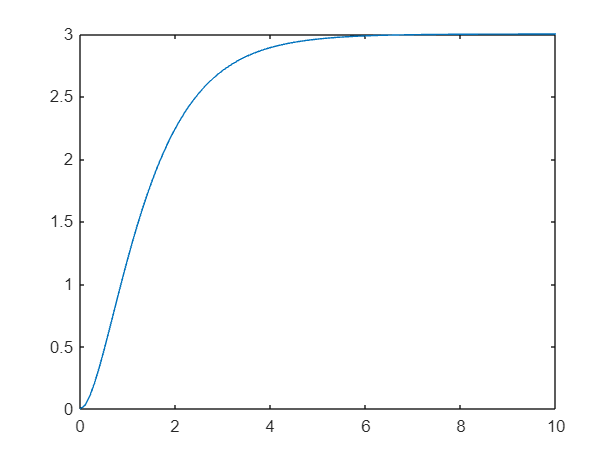

plot(t_,subs(y, t, t_))

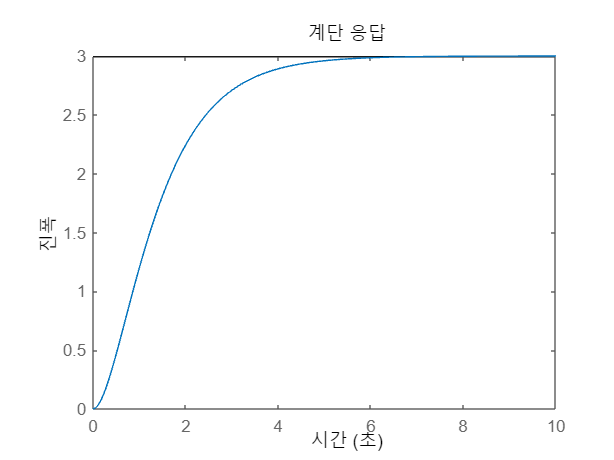

sys = ss(A, B, C ,D);
step(sys, 10)

x0 = [0.1,0]

x0 =     0.1000         0


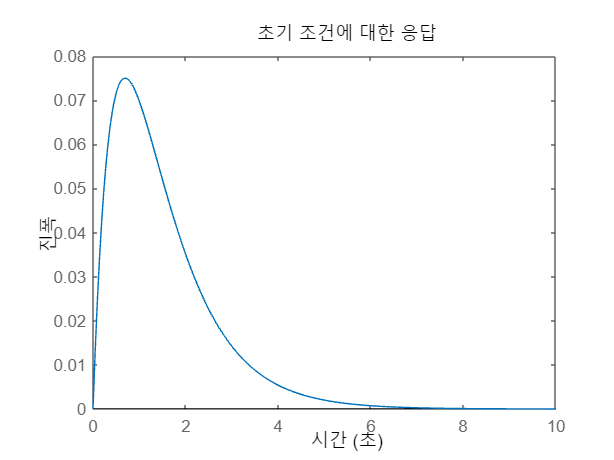

initial(sys,x0,10)